we declare the parameters defining the geometry of the domain

D = 0.10;              %diameter of pipe in meters
Wb = 0.75;             %bulk velocity at inlet in m/s
rho = 998.23;          %density in kg/m^3
ni = 1e-6;             %kynematic viscosity in m^2/s
mu = rho * ni;         %dynamic viscosity in Pa * s
Re = Wb * D / ni 

Re = 7.5000e+04

%import the simulation data to be processed
path_phi_file = 'folder_for_phi_file'+'name_of_simulation.phi';
path_mat_file = 'folder_for_mat_file'+'name_of_simulation.mat';
%create workspace (mat file) from simulation (phi file)
data_simulation(path_phi_file, path_mat_file)
%load the workspace
load(path_mat_file)

YPLS=squeeze(YPLS)
min(YPLS(17, :))
max(YPLS(17, :))

 we want to plot the variation along z of the z-velocity, to see where it starts to be negligible, that is where the flow can be considered fully developed. Note that DWDZ is stored in the centre of the cells in Phoenics, while W1 is stored in the 'H'  faces.Z_C = squeeze(Z_C);

Z_C = squeeze(Z_C);
DWDZ = squeeze(DWDZ);

figure()
plot(Z_C, abs(DWDZ(1, :)), 'r-', 'LineWidth', 1, 'MarkerSize', 1);
hold on;
y_idx = ceil(0.5*length(Y_C)); %% idx of the cell at half radius
plot(Z_C, abs(DWDZ(y_idx, :)), 'b-', 'LineWidth', 1, 'MarkerSize', 1);
plot(Z_C, abs(DWDZ(end, :)), 'g-', 'LineWidth', 1, 'MarkerSize', 1);
yline(0.01, 'k--')
title('|dw/dz|')
legend('at the axis', 'at half radius','at the wall', 'threshold of 0.01')
ylim([0, 0.5])
hold off;

W1 = squeeze(W1);
Z_H = squeeze(Z_H);
figure()
plot(Z_H, abs(W1(1, :)), 'r-', 'LineWidth', 1, 'MarkerSize', 1);
hold on;
plot(Z_H, abs(W1(y_idx, :)), 'b-', 'LineWidth', 1, 'MarkerSize', 1);
plot(Z_H, abs(W1(end, :)), 'g-', 'LineWidth', 1, 'MarkerSize', 1);
xline(0.85*5)
ylim([0.5, 1])
title('z-velocity')
legend('at the axis', 'at half radius', 'at the wall', '85% of length', 'Location','south')
hold off;
%Now we obtain the first value such that the derivative is under the
%threshold
threshold = 0.01;
counter=1;
while (max(abs(DWDZ(:, counter))) > threshold) || (Z_C(counter)<=3)
counter=counter+1;
end

counter

Now to check for the physical soundness of the solution, we plot the pression and velocity profiles along some segments

Z_C = squeeze(Z_C);
P1 = squeeze(P1);
figure()
subplot(3, 1, 1)
plot(Z_C, P1(1, :), 'r-o', 'LineWidth', 1, 'MarkerSize', 1)
hold on;
plot(Z_C, (P1(1, end)-P1(1, 1))/(Z_C(end)-Z_C(1)).*Z_C  + P1(1, 1), 'k--') %retta tra punto iniziale e punto finale
m = (P1(1, end)-P1(1, counter))/(Z_C(end)-Z_C(counter)); %only in the fully developed region
intercept = P1(1, end) - m*Z_C(end);
plot(Z_C(counter:end), m*Z_C(counter:end) + intercept, 'g-^', 'MarkerSize', 1)
title("Pression at the axis")
legend("Pression", "Line between extremals", 'Line in f.d. region')
hold off

subplot(3, 1, 2)
y_idx = ceil(0.5*length(Y_C)); %% idx of the cell at half radius
plot(Z_C, P1(y_idx, :), 'r-o', 'LineWidth', 1, 'MarkerSize', 1)
hold on;
plot(Z_C, (P1(y_idx, end)-P1(y_idx, 1))/(Z_C(end)-Z_C(1)).*Z_C  + P1(y_idx, 1), 'k--') %retta tra punto iniziale e punto finale
m = (P1(y_idx, end)-P1(y_idx, counter))/(Z_C(end)-Z_C(counter)); %only in the fully developed region
intercept = P1(y_idx, end) - m*Z_C(end);
plot(Z_C(counter:end), m*Z_C(counter:end) + intercept, 'g-^', 'MarkerSize', 1)
title("Pression at half radius")
legend("Pression", "Line between extremals", 'Line in f.d. region')
hold off

subplot(3, 1, 3)
plot(Z_C, P1(end, :), 'r-o', 'LineWidth', 1, 'MarkerSize', 1)
hold on;
plot(Z_C, (P1(end, end)-P1(end, 1))/(Z_C(end)-Z_C(1)).*Z_C  + P1(end, 1), 'k--')
m = (P1(end, end)-P1(end, counter))/(Z_C(end)-Z_C(counter));
intercept = P1(end, end) - m*Z_C(end);
plot(Z_C(counter:end), m*Z_C(counter:end) + intercept, 'g-^', 'MarkerSize', 1)
title("Pression at the wall")
legend("Pression", "Line between extremals", 'Line in f.d. region')
hold off

Y_C = squeeze(Y_C);
W1 = squeeze(W1);
figure()
plot(Y_C, W1(:, 2), 'b--', 'LineWidth', 1, 'MarkerSize', 4)
hold on;
plot(Y_C, W1(:, ceil(0.25*length(Z_C))), 'c-+', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C, W1(:, ceil(0.50*length(Z_C))), 'm-x', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C, W1(:, ceil(0.75*length(Z_C))), 'm-x', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C, W1(:, ceil(0.90*length(Z_C))), 'k-.', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C, W1(:, ceil(0.95*length(Z_C))), 'r-o', 'LineWidth', 1, 'MarkerSize', 4)
plot(Y_C, W1(:, length(Z_C)), 'g-^', 'LineWidth', 1, 'MarkerSize', 4)
title("z-velocity wrt radius")
legend("W at inlet+1", "W at 25% of length", "W at 50% of length", "W at 75% of length", "W at 90% of length", "W at 95% of length", "W at end of pipe")
hold off
figure()
plot(Z_H, W1(1, :), 'r-.', 'LineWidth', 1.5)
title("W along the central axis")

Now we investigate the plots of 𝑘/𝑊𝑏^2 versus 𝑟/𝑅 and 𝜀𝑅/𝑊𝑏^3 versus 𝑟/𝑅

z_idx = 1400; %choose index in fully developed region
KE = squeeze (KE);
EP = squeeze (EP);
r_norm = Y_C./Y_C(end);
plot(r_norm, KE(:, z_idx)./(Wb^2), 'b-', LineWidth=2)
hold on
plot(r_norm, EP(:, z_idx)./(Wb^3), 'r-', LineWidth=2)
legend('kynetic energy', 'dissipation rate', 'Location', 'north')
hold off

The next graphs are intended to study the grid independence of the results

Import all of the simulation data:

%import the simulation data to be processed
data_simulation('C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\matlab\codes\base1.phi', 'C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\matlab\codes\base1.mat')

NVariabili = 13

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\matlab\codes\base1.mat')

P = squeeze(P1);
W = squeeze(W1);
dwdy = squeeze(DWDY);
k = squeeze(KE);
eps = squeeze (EP);

YC = squeeze(Y_C);
YN = squeeze(Y_N);
ZC = squeeze (Z_C);
ZH = squeeze (Z_H);


data_simulation('C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\matlab\codes\coarse-11x1500.phi', 'C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\matlab\codes\coarse.mat')

NVariabili = 13

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\matlab\codes\coarse.mat')
Py1 = squeeze(P1);
Wy1 = squeeze(W1);
dwdyy1 = squeeze(DWDY);
ky1 = squeeze(KE);
epsy1 = squeeze (EP);

YCy1 = squeeze(Y_C);
YNy1 = squeeze(Y_N);
ZCy1 = squeeze (Z_C);
ZHy1 = squeeze (Z_H);



data_simulation('C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\matlab\codes\refined-20x1500.phi', 'C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\matlab\codes\refined.mat')

NVariabili = 13

operazione = 'acquisizione'

operazione = 'scrittura coordinate facce celle'

operazione = 'scrittura matrice delle variabili'

load('C:\Users\marta\OneDrive - Politecnico di Milano\AAAUNI\MAGISTRALE\PRIMO ANNO\FLUID LABS\Lab_tests\CFD2\matlab\codes\refined.mat')
Py2 = squeeze(P1);
Wy2 = squeeze(W1);
dwdyy2 = squeeze(DWDY);
ky2 = squeeze(KE);
epsy2 = squeeze (EP);

YCy2 = squeeze(Y_C);
YNy2 = squeeze(Y_N);
ZCy2 = squeeze (Z_C);
ZHy2 = squeeze (Z_H);

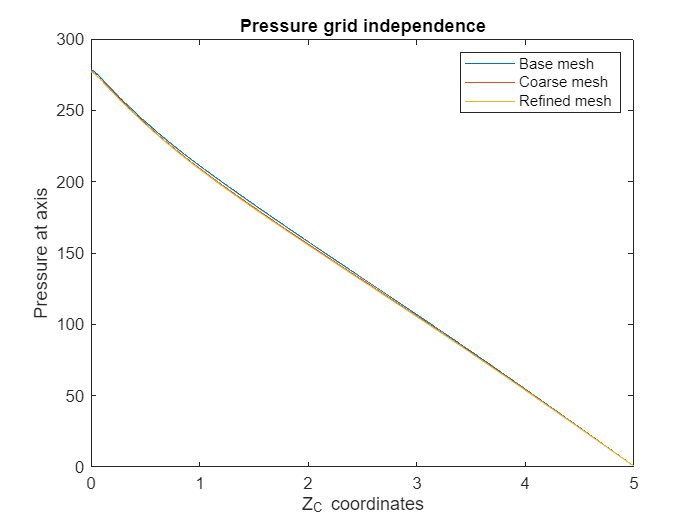

figure()

plot(ZC, P(1, :), ZCy1, Py1(1, :), ZCy2, Py2(1, :))
legend('Base mesh', 'Coarse mesh', 'Refined mesh')
xlabel('Z_C coordinates')
ylabel('Pressure at axis')
title('Pressure grid independence')

% Compute area under the absolute value of the curve
A_base     = trapz(ZC, abs(P(1, :)));
A_coarse   = trapz(ZCy1, abs(Py1(1, :)));
A_refined  = trapz(ZCy2, abs(Py2(1, :)));

% Compute relative differences
rel_diff_base   = max(abs(A_refined - A_base) ./ A_base)

rel_diff_base = 0.0115

rel_diff_coarse = max(abs(A_base - A_coarse) ./ A_coarse)

rel_diff_coarse = 0.0087

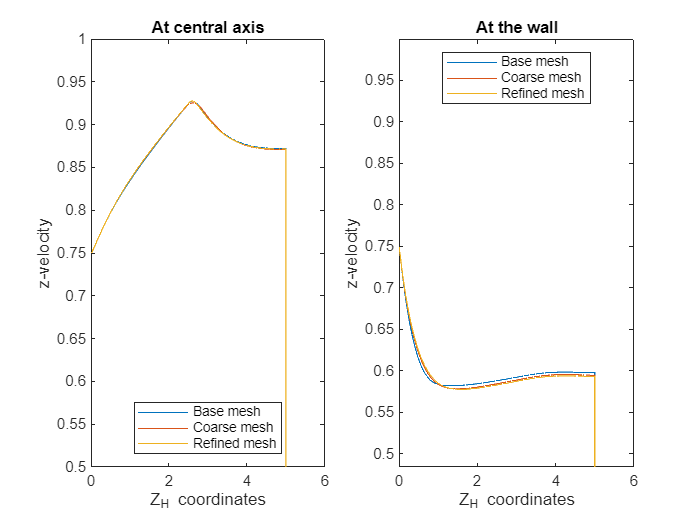

figure()
%At the central axis
subplot(1, 2, 1)
plot(ZH, W(1,:), ZHy1, Wy1(1,:), ZHy2, Wy2(1,:))
legend('Base mesh', 'Coarse mesh', 'Refined mesh', 'Location','south')
xlabel('Z_H coordinates')
ylabel('z-velocity')
ylim([0.5, 1])
title('At central axis')

%Near the wall
subplot(1, 2, 2)
plot(ZH, W(end,:), ZHy1, Wy1(end,:), ZHy2, Wy2(end,:))
legend('Base mesh', 'Coarse mesh', 'Refined mesh', 'Location','north')
xlabel('Z_H coordinates')
ylabel('z-velocity')
ylim([0.5, 1])
title('At the wall')

% Compute area under the absolute value of the curve
A_base     = trapz(ZH, abs(W(1, :)));
A_coarse   = trapz(ZHy1, abs(Wy1(1, :)));
A_refined  = trapz(ZHy2, abs(Wy2(1, :)));

% Compute relative differences
rel_diff_base   = max(abs(A_refined - A_base) ./ A_base)

rel_diff_base = 1.0533e-04

rel_diff_coarse = max(abs(A_base - A_coarse) ./ A_coarse)

rel_diff_coarse = 3.4409e-05

A_base     = trapz(ZH, abs(W(ceil(end*0.5), :)));
A_coarse   = trapz(ZHy1, abs(Wy1(ceil(end*0.5), :)));
A_refined  = trapz(ZHy2, abs(Wy2(ceil(end*0.5), :)));

% Compute relative differences
rel_diff_base   = max(abs(A_refined - A_base) ./ A_base)

rel_diff_base = 0.0057

rel_diff_coarse = max(abs(A_base - A_coarse) ./ A_coarse)

rel_diff_coarse = 0.0124

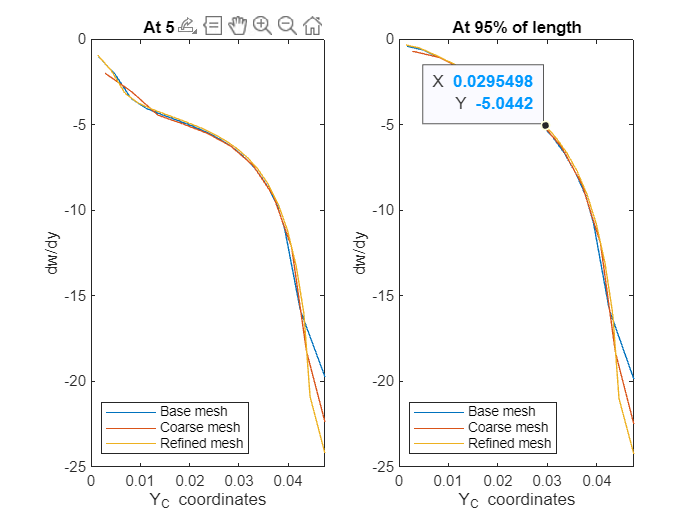


figure()
%At 50% of length
subplot(1, 2, 1)
plot(YC, dwdy(:, ceil(end*0.5)), YCy1, dwdyy1(:, ceil(end*0.5)), YCy2, dwdyy2(:, ceil(end*0.5)))
legend('Base mesh', 'Coarse mesh', 'Refined mesh', 'Location','southwest')
xlabel('Y_C coordinates')
ylabel('dw/dy')
title('At 50% of length')


%At 95% of length
subplot(1, 2, 2)
plot(YC, dwdy(:, ceil(end*0.95)), YCy1, dwdyy1(:, ceil(end*0.95)), YCy2, dwdyy2(:, ceil(end*0.95)))
legend('Base mesh', 'Coarse mesh', 'Refined mesh', 'Location','southwest')
xlabel('Y_C coordinates')
ylabel('dw/dy')
title('At 95% of length')

% Compute area under the absolute value of the curve
A_base     = trapz(YC, abs(dwdy));
A_coarse   = trapz(YCy1, abs(dwdyy1));
A_refined  = trapz(YCy2, abs(dwdyy2));

% Compute relative differences
rel_diff_base   = max(abs(A_refined - A_base) ./ A_base)

rel_diff_base = 0.1653

rel_diff_coarse = max(abs(A_base - A_coarse) ./ A_coarse)

rel_diff_coarse = 0.1295

% Compute area under the absolute value of the curve
A_base     = trapz(YC, abs(dwdy(:, ceil(end*0.95))));
A_coarse   = trapz(YCy1, abs(dwdyy1(:, ceil(end*0.95))));
A_refined  = trapz(YCy2, abs(dwdyy2(:, ceil(end*0.95))));

% Compute relative differences
rel_diff_base   = max(abs(A_refined - A_base) ./ A_base)

rel_diff_base = 0.0208

rel_diff_coarse = max(abs(A_base - A_coarse) ./ A_coarse)

rel_diff_coarse = 0.0212


% Compute area under the absolute value of the curve
A_base     = trapz(YC, abs(dwdy(:, ceil(end*0.5))));
A_coarse   = trapz(YCy1, abs(dwdyy1(:, ceil(end*0.5))));
A_refined  = trapz(YCy2, abs(dwdyy2(:, ceil(end*0.5))));

% Compute relative differences
rel_diff_base   = max(abs(A_refined - A_base) ./ A_base)

rel_diff_base = 0.0218

rel_diff_coarse = max(abs(A_base - A_coarse) ./ A_coarse)

rel_diff_coarse = 0.0183

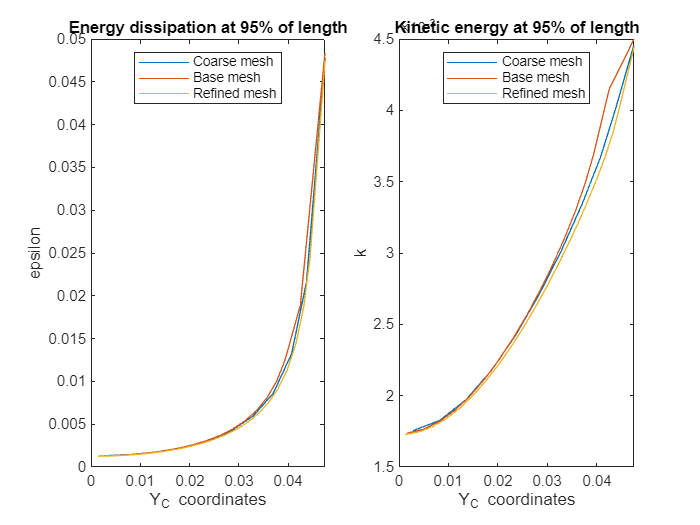

z = ceil(0.95*length(ZC));
z1 = ceil(0.95*length(ZCy1));
z2 = ceil(0.95*length(ZCy2));

k = squeeze(k);
ky1 = squeeze(ky1);
ky2 = squeeze(ky2);
eps = squeeze(eps);
epsy1 = squeeze(epsy1);
epsy2 = squeeze(epsy2);

subplot(1, 2, 1)
plot(YCy1, epsy1(:, z1), YC, eps(:, z), YCy2, epsy2(:, z2))
legend('Coarse mesh', 'Base mesh', 'Refined mesh', 'Location','north')
xlabel('Y_C coordinates')
ylabel('epsilon')
title('Energy dissipation at 95% of length')

subplot(1, 2, 2)
plot(YCy1, ky1(:, z1), YC, k(:, z), YCy2, ky2(:, z2))
legend('Coarse mesh', 'Base mesh', 'Refined mesh', 'Location','north')
xlabel('Y_C coordinates')
ylabel('k')
title('Kinetic energy at 95% of length')

Validation study for frictional losses

deltaP = P(1, ceil(0.9*end))-P(1, 0.95*end);
L = ZC(ceil(0.95*end))-ZC(ceil(0.9*end));
f = (2*D*deltaP)/(rho*L*Wb^2)

f = 0.0192

%WRT Torbergsen value
f_tor = 0.0190;
abs(f-f_tor)/f_tor

ans = 0.0131

%Resolve prandtl formula with newton method
x0 = 0.02;
g = @(x) 2*log10(2.51/(Re * sqrt(x))) + 1./sqrt(x);
dg = @(x) - 1/2*x^(-3/2) - 1/(x * log(10));
tol = 1e-7;
maxIter = 100000;
format long
[x_root, success] = newton(g, dg, x0, tol, maxIter)

x_root =    0.019118573042822


success = logical
   1


%Haaland formula
f_Ha = ( -1.8 * log10(6.9 / Re) )^(-2)

f_Ha =    0.018945541122803
